# `MATH 3620 Numerical Analysis`

# `Homework 6`

# `25 Mar 2021`

close all; clear all ; clc;

## `Q1. Plotting Legendre Polynomials`

% obtain Legendre polynomials
syms x
% domain
domain = [-1 1];
% first Legendre polynomial
L0 = 1

L0 = 1

% second Legendre polynomial
a0 = int(x*L0*L0, x, domain)/int(L0*L0, x, domain);
L1 = x - a0

$$L1 = x$$

% third Legendre polynomial
a1 = int(x*L1*L1, x, domain)/int(L1*L1, x, domain);
beta1 = int(L1*L1, x, domain)/int(L0*L0, x, domain);
L2 = (x - a1)*L1 - beta1*L0

$$L2 = x^{2}-\frac{1}{3}$$

% fourth Legendre polynomial
a2 = int(x*L2*L2, x, domain)/int(L2*L2, x, domain);
beta2 = int(L2*L2, x, domain)/int(L1*L1, x, domain);
L3 = (x - a2)*L2 - beta2*L1;
L3 = simplify(L3)

$$L3 = x^{3}-\frac{3\,x}{5}$$

% fifth Legendre polynomial
a3 = int(x*L3*L3, x, domain)/int(L3*L3, x, domain);
beta3 = int(L3*L3, x, domain)/int(L2*L2, x, domain);
L4 = (x - a3)*L3 - beta3*L2;
L4 = simplify(L4)

$$L4 = x^{4}-\frac{6\,x^{2}}{7}+\frac{3}{35}$$

% sixth Legendre polynomial
a4 = int(x*L4*L4, x, domain)/int(L4*L4, x, domain);
beta4 = int(L4*L4, x, domain)/int(L3*L3, x, domain);
L5 = (x - a4)*L4 - beta4*L3;
L5 = simplify(L5)

$$L5 = x^{5}-\frac{10\,x^{3}}{9}+\frac{5\,x}{21}$$

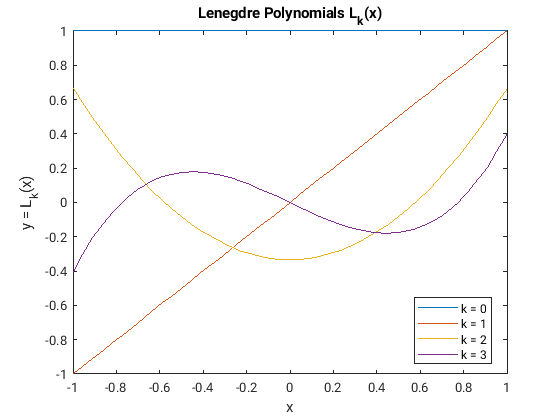

% plot Lengendre polynomials
fplot(L0, domain)
hold on
fplot(L1, domain)
fplot(L2, domain)
fplot(L3, domain)
hold off
xlabel('x')
ylabel('y = L_k(x)')
legend('k = 0', 'k = 1', 'k = 2', 'k = 3', 'location', 'best')
title('Lenegdre Polynomials L_k(x)')

## `Q2. Approximating f(x) = exp(x)`

% function to be approximated
f = exp(x);

% find least squares approximation using Legendre polynomials
L = [L0 L1 L2 L3];
pL = 0;
for i = 1:length(L)
    coeff = int(f*L(i), x, domain)/int(L(i)*L(i), x, domain);
    pL = pL + coeff*L(i);
end
pL = simplify(pL)

$$pL = \frac{\mathrm{e}}{2}-\frac{{\mathrm{e}}^{-1}}{2}+3\,x\,{\mathrm{e}}^{-1}+\frac{35\,{\mathrm{e}}^{-1}\,\left(5\,{\mathrm{e}}^{2}-37\right)\,\left(\frac{3\,x}{5}-x^{3}\right)}{4}+\frac{15\,{\mathrm{e}}^{-1}\,\left(x^{2}-\frac{1}{3}\right)\,\left({\mathrm{e}}^{2}-7\right)}{4}$$

% Chebyshev approximation of degree 3
C = genChebyshev(4)

$$C = \left(\begin{array}{cccc} 1 & x & 2\,x^{2}-1 & 2\,x\,\left(2\,x^{2}-1\right)-x \end{array}\right)$$

coeffs = zeros(1, 4);
g = sqrt(1 - x*x);
for i = 1:length(coeffs)
    hx = C(i)*f/g;
    coeffs(i) = vpa((2/pi)*int(hx, x, -1, 1), 5);
end
C3 = sum([coeffs(1)/2 coeffs(2) coeffs(3) coeffs(4)].*C);
C3 = vpa(C3, 5)

$$C3 = 1.086\,x+0.54298\,x^{2}+0.088672\,x\,\left(2.0\,x^{2}-1.0\right)+0.99457$$

% Taylor series of degree 3 (about x = 0, mid-point of domain)
a = 0;
fx = diff(f, x);
f2x = diff(fx, x);
f3x = diff(f2x, x);
T3 = subs(f, x, a) + subs(fx, x, a)*(x - a) + subs(f2x, x, a)*(x - a)^2 + subs(f3x, x, a)*(x - a)^3;
T3 = simplify(T3)

$$T3 = x^{3}+x^{2}+x+1$$

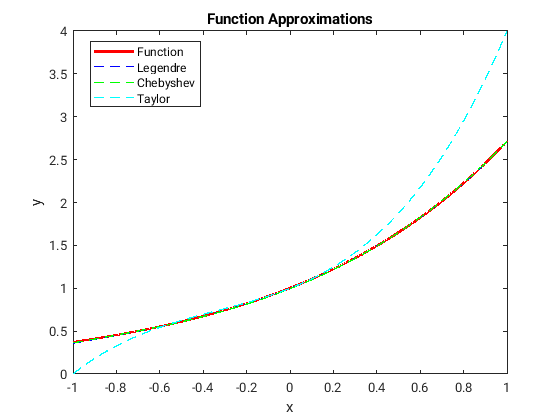

% plot all approximations and compute errors
func = @(t) exp(t);
Plegendre = @(t) exp(1)/2 - exp(-1)/2 + 3*t*exp(-1) + (35*exp(-1)*(5*exp(2) - 37))*((3*t)/5 - t.^3)/4 + (15*exp(-1))*(t.^2 - (1/3))*(exp(2) - 7)/4;
PChebyshev = @(t) 1.086*t + 0.54298*t.^2 + 0.088672*t.*(2.0*t.^2 - 1.0) + 0.99457;
PTaylor = @(t) 1 + t + t.^2 + t.^3;

% plot approximations
t = linspace(domain(1), domain(2), 1000);
plot(t, func(t), 'r', 'LineWidth', 2)
hold on
plot(t, Plegendre(t), 'b--', 'LineWidth', 1 )
plot(t, PChebyshev(t), 'g--', 'LineWidth', 1 )
plot(t, PTaylor(t), 'c--', 'LineWidth', 1 )
hold off
xlabel('x')
ylabel('y')
legend('Function', 'Legendre', 'Chebyshev', 'Taylor', 'location', 'best')
title('Function Approximations')

% print and compare errors
errtable = table;
errtable.Approximation = ["Legendre" "Chebyshev" "Taylor"]';
errtable.Infinity_Norm_Error = [norm(func(t) - Plegendre(t), 1) norm(func(t) - PChebyshev(t), 1) norm(func(t) - PTaylor(t), 1)]';
errtable.L2_Norm_Error = [norm(func(t) - Plegendre(t), 2) norm(func(t) - PChebyshev(t), 2) norm(func(t) - PTaylor(t), 2)]';
errtable

errtable = 3×3 table
    Approximation    Infinity_Norm_Error    L2_Norm_Error
    _____________    ___________________    _____________

     "Legendre"            2.8669               0.106    
     "Chebyshev"           3.4517              0.1217    
     "Taylor"              215.98              11.937    


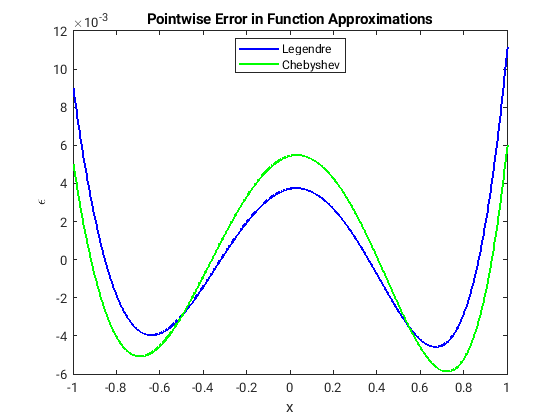

% plot pointwise errors
plot(t, func(t) - Plegendre(t), 'b', 'LineWidth', 1.5 )
hold on
plot(t, func(t) - PChebyshev(t), 'g', 'LineWidth', 1.5 )
hold off
xlabel('x')
ylabel('\epsilon')
legend('Legendre', 'Chebyshev', 'location', 'best')
title('Pointwise Error in Function Approximations')

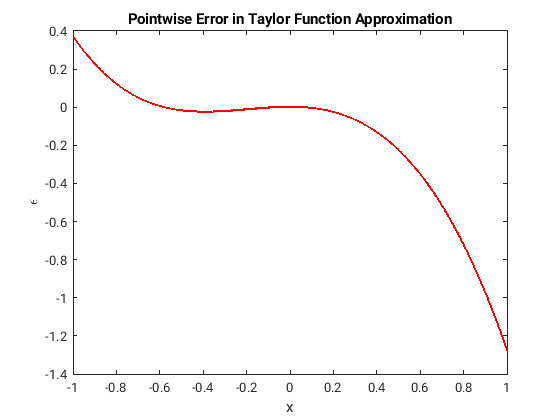


plot(t, func(t) - PTaylor(t), 'r', 'LineWidth', 1.5 )
xlabel('x')
ylabel('\epsilon')
title('Pointwise Error in Taylor Function Approximation')

`Comments:`` The pointwise error for the Legendre and Chebyshev approximations are well bounded and do-not follow any particular trend. In case of The Taylor approximation, the errors are low near the point of expansion, but grow fast as we move away.`

## `Q3. Exponential Least Squares`

t = [1 2 3 4];
c = [0.91 0.8 0.76 .65];

% c = b*exp(-a*t)
% ln(c) = ln(b) + (-a)*t
% p = a_0 + a_1*t

% build system of equations
A = [sum(ones(size(t))) sum(t); sum(t) sum(t.^2)];
b = [sum(log(c)) sum(log(c).*t)]';
coeffs = A\b;
b = exp(coeff(1));
a = -coeffs(2);

% print LSA
fprintf('The Least Squares Approximation is c = %.4f*exp(-%.4f*t)\n', b, a)

The Least Squares Approximation is c = 1.1926*exp(-0.1061*t)


% print errors
J = c - b*exp(-a*t);
J = sum(J.^2);
fprintf('Square error = %.6f\n', J)

Square error = 0.082071


## `Q4. Quadratic Least Squares`

`We have to minimize`


$$J = \sum_{j=1}^N [f_j - (ax_j + bx_j^2)]^2$$


`which requires that `


$$\frac{\partial J}{\partial a} = 0,  \frac{\partial J}{\partial b} = 0  $$


`The conditions result in the following equations.`

$2\sum_{j = 1}^{N} (f_j - ax_j - bx_j^2)(-x_j) = 0$ `and`


$$2\sum_{j = 1}^{N} (f_j - ax_j - bx_j^2)(-x_j^2) = 0$$


`which can be written as`

$a\sum_{j=1}^{N} x_j^2 + b\sum_{j=1}^{N} x_j^3 = \sum_{j=1}^{N} f_jx_j$ `and`


$$a\sum_{j = 1}^{N} x_j^3 + b\sum_{j=1}^{N} x_j^4 = \sum_{j=1}^{N} f_jx_j^2
$$


`The equations can be solved for 'a' and 'b'.`

x = [1 2 3 4];
y = [3.1 9.8 21.2 36.1];

% build system of equations
A = [sum(x.^2) sum(x.^3); sum(x.^3) sum(x.^4)];
b = [sum(y.*x) sum(y.*(t.^2))]';
coeffs = A\b;
a = coeffs(1);
b = coeffs(2);

% print LSA
fprintf('The Least Squares Approximation is y = %.4fx + %.4fx^2\n', a, b)

The Least Squares Approximation is y = 0.9642x + 2.0177x^2


% print errors
J = y - a*x - b*x.^2;
J = sum(J.^2);
fprintf('Square error = %.6f\n', J)

Square error = 0.077161


## `Function Definitions`

function T = genChebyshev(n)
    % borrowed from HW3
    % this function generates first n Chebyshev polynomials on [-1, 1]
    syms x
    if n == 0
        T = [1];
    end
    if n == 1
            T = [1 x];
    else
        T = [1 x];
        for j = 2:n-1
            T(j+1) = 2*x*T(j) - T(j-1);
        end
    end
end